***Importar archivo Excel***

clear all

% Set up the Import Options and import the data
opts2 = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts2.DataLines = [2, Inf];
opts2.Delimiter = ",";

% Specify column names and types
opts2.VariableNames = ["Identifier_IndexHardness_MPa_ReducedMod__MPa_PosY_um_PosZ_um_Co", "Var2", "Var3"];
opts2.VariableTypes = ["datetime", "duration", "string"];

% Specify file level properties
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% Specify variable properties
opts2 = setvaropts(opts2, "Var3", "WhitespaceRule", "preserve");
opts2 = setvaropts(opts2, "Var3", "EmptyFieldRule", "auto");
opts2 = setvaropts(opts2, "Identifier_IndexHardness_MPa_ReducedMod__MPa_PosY_um_PosZ_um_Co", "InputFormat", "yyyy-MM-dd", "DatetimeFormat", "preserveinput");
opts2 = setvaropts(opts2, "Var2", "InputFormat", "hh:mm:ss.S");

% Import the data
x27CoNi_150x150_1um_2025_03_31_13h50m05s = readtimetable("C:\Users\franc\Documents\Trabajo\Colaboraciones\Mariana Pinto\27CoNi_150x150_1um_2025-03-28,10h07m58s\results\27CoNi_150x150_1um_2025-03-31,13h50m05s.txt", opts2, "RowTimes", "Identifier_IndexHardness_MPa_ReducedMod__MPa_PosY_um_PosZ_um_Co");

% Clear temporary variables
clear opts2

% Display results
x27CoNi_150x150_1um_2025_03_31_13h50m05s

excel_file = 22500×3 table
    Identifier_IndexHardness_MPa_ReducedMod__MPa_PosY_um_PosZ_um_Co       Var2                                  Var3                           
    _______________________________________________________________    __________    __________________________________________________________

                              2025-03-24                               17:07:30.0    " 4/0→18403.37195→285683.374942→131.999→131.985→"     
                              2025-03-24                               17:07:30.0    " 4/1→12461.422084→257017.772536→132.98→131.98→"      
                              2025-03-24                               17:07:30.0    " 4/2→23877.992091→338539.52686→134.03→131.98→"       
                              2025-03-24                               17:07:30.0    " 4/3→22184.510479→292469.328089→135.039→131.98→"     
                      

Acondicionamiento del Excel: corregir posición estableciendo el 0, cambio de unidades de MPa a GPa, eliminar filas vacías

% Obtener el número de filas en tu tabla
num_filas = size(excel_file, 1);

% Inicializar el vector correct_PosZ
excel_file.PosZ = zeros(num_filas, 1);
excel_file.PosY= zeros(num_filas, 1);
excel_file.Hardness_GPa = zeros(num_filas, 1);
excel_file.ReducedMod_GPa = zeros(num_filas, 1);

% Iterar sobre cada fila y restar el último valor de esa fila
for i = 1:num_filas
    % Establecer el 0
    excel_file.PosZ(i) = round(excel_file.PosZ_um_(i) - excel_file.PosZ_um_(1),0); 
    excel_file.PosY(i) = round(excel_file.PosY_um_(i) - excel_file.PosY_um_(1),0);
    % MPa a GPa
    excel_file.Hardness_GPa(i) = excel_file.Hardness_MPa_(i).*10^-3;
    excel_file.ReducedMod_GPa(i) = excel_file.ReducedMod__MPa_(i).*10^-3;
end

rowswithNaN=isnan(excel_file.Hardness_MPa_) | isnan(excel_file.ReducedMod__MPa_);
cleandata=excel_file(~rowswithNaN,:);
% Eliminar la primera fila (encabezados)
cleandata(1, :) = [];

excel_file

***Importar TXT***

clear all
filePath = "C:\Users\franc\Documents\Trabajo\Colaboraciones\Mariana Pinto\27CoNiCr_150x150_1um_2025-04-02,10h53m50s\results\27CoNiCr_150x150_1um.txt";              
opts = detectImportOptions(filePath, 'Delimiter', '\t');
data = readtable(filePath, opts);


% Acondicionamiento: establecer posición 0, cambio unidades MPa a GPa
num_filas = size(data, 1);

data.PosZ = zeros(num_filas, 1);
data.PosY= zeros(num_filas, 1);
data.Hardness_GPa = zeros(num_filas, 1);
data.ReducedMod_GPa = zeros(num_filas, 1);

poisson_i = 0.07; % Poisson indentador (diamante)
poisson_m = 0.3; % Poisson material
E_i = 1140; % E indentador (diamante)

for i = 1:num_filas
    % Establecer el 0
    data.PosZ(i) = round(data.PosZ_um_(i) - data.PosZ_um_(1),0); 
    data.PosY(i) = round(data.PosY_um_(i) - data.PosY_um_(1),0);
    % MPa a GPa
    data.Hardness_GPa(i) = data.Hardness_MPa_(i).*10^-3;
    data.ReducedMod_GPa(i) = data.ReducedMod__MPa_(i).*10^-3;
    data.materialmodulus_GPa(i) = ((1-poisson_m^2).*(E_i.*data.ReducedMod_GPa(i)))/(E_i-(data.ReducedMod_GPa(i).*(1-poisson_i^2)));
end

rowswithNaN=isnan(data.Hardness_MPa_) | isnan(data.ReducedMod__MPa_);
cleandata=data(~rowswithNaN,:);
% Eliminar la primera fila (encabezados)
cleandata(1, :) = [];


***Histogramas***

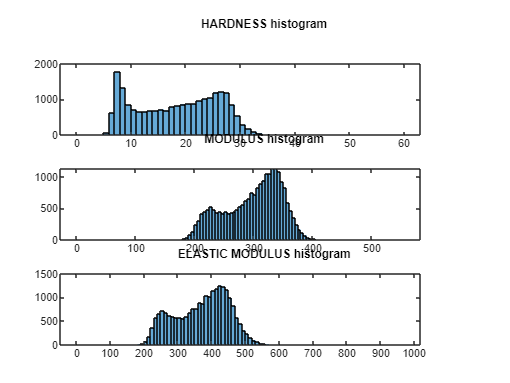

subplot(3,1,1)
histogram(cleandata.Hardness_GPa)
title("HARDNESS histogram")

subplot(3,1,2)
histogram(cleandata.ReducedMod_GPa)
title("MODULUS histogram")

subplot(3,1,3)
histogram(cleandata.materialmodulus_GPa)
title("ELASTIC MODULUS histogram")

***Contour plots***

% Ordenar X e Y en orden ascendente
Y_sorted = sort(unique(round(cleandata.PosY,0)));
Z_sorted = sort(unique(round(cleandata.PosZ,0)));

% Definir la cuadrícula para la interpolación
[z_grid, y_grid] = meshgrid(Z_sorted, Y_sorted);

% Interpolar HARDNESS
Z1_interpolated = griddata(cleandata.PosY, cleandata.PosZ, cleandata.Hardness_GPa, z_grid, y_grid, 'nearest');

% Interpolar MODULUS
Z2_interpolated = griddata(cleandata.PosY, cleandata.PosZ, cleandata.ReducedMod_GPa, z_grid, y_grid, 'nearest');

% Interpolar MATERIAL MODULUS
Z3_interpolated = griddata(cleandata.PosY, cleandata.PosZ, cleandata.materialmodulus_GPa, z_grid, y_grid, 'nearest');

% Define the limit values of the hardness (1), reduced modulus (2) and elastic modulus (3) contour plots
vmin1 = 5;
vmax1 = 32;
vmin2 = 190;
vmax2 = 400;
vmin3 = 200;
vmax3 = 530;


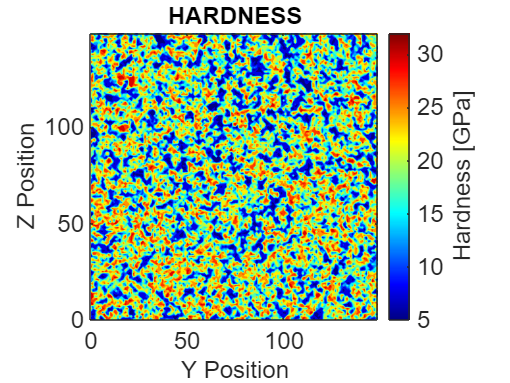

levels = 10;

% HARDNESS contour plot

% Recortar los valores interpolados según vmin/vmax
Z1_matrix_clipped = min(max(Z1_interpolated, vmin1), vmax1);

figure;
% Crear el gráfico de contorno lleno (contourf)
contourf(Y_sorted, Z_sorted, Z1_matrix_clipped, levels,'LineStyle', 'none');

% Colocar la barra de color
cbar1 = colorbar;
cbar1.Label.String = 'Hardness [GPa]';
cbar1.Label.FontSize = 18;

% Modificar los límites de la colorbar
clim([vmin1, vmax1]); % Utiliza caxis para establecer los límites

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar1.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('Y Position', 'FontSize', 18);
ylabel('Z Position', 'FontSize', 18);

% Establecer el título del subplot
title('HARDNESS', 'FontSize', 18);

colormap('jet');

axis equal

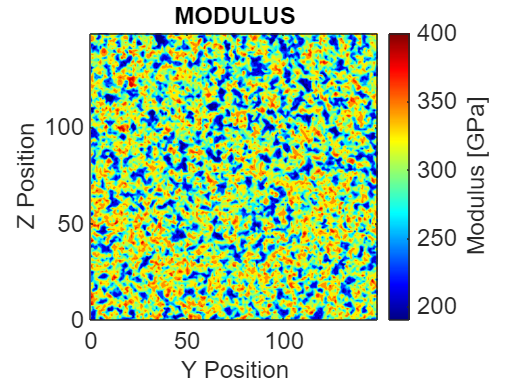


% REDUCED MODULUS contour plot

% Recortar los valores interpolados según vmin/vmax
Z2_matrix_clipped = min(max(Z2_interpolated, vmin2), vmax2);

figure;
% Crear el gráfico de contorno lleno (contourf)
contourf(Y_sorted, Z_sorted, Z2_matrix_clipped, levels, 'LineStyle', 'none');

% Colocar la barra de color
cbar2 = colorbar;
cbar2.Label.String = 'Modulus [GPa]';
cbar2.Label.FontSize = 18;

% Modificar los límites de la colorbar
clim([vmin2, vmax2]); % Utiliza caxis para establecer los límites

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar2.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('Y Position', 'FontSize', 18);
ylabel('Z Position', 'FontSize', 18);

% Establecer el título del subplot
title('MODULUS', 'FontSize', 18);

colormap('jet');

axis equal

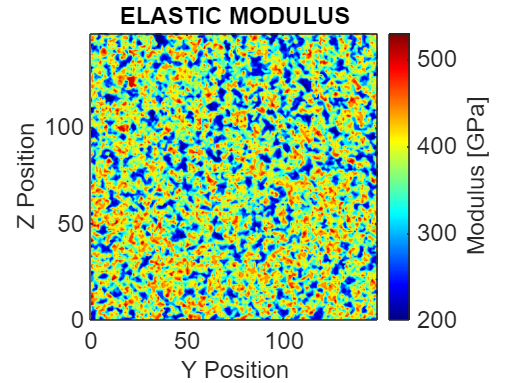


figure;

% ELASTIC MODULUS contour plot

% Recortar los valores interpolados según vmin/vmax
Z3_matrix_clipped = min(max(Z3_interpolated, vmin3), vmax3);

% Crear el gráfico de contorno lleno (contourf)
contourf(Y_sorted, Z_sorted, Z3_matrix_clipped, levels, 'LineStyle', 'none');

% Colocar la barra de color
cbar3 = colorbar;
cbar3.Label.String = 'Modulus [GPa]';
cbar3.Label.FontSize = 18;

% Modificar los límites de la colorbar
clim([vmin3, vmax3]); % Utiliza caxis para establecer los límites

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar3.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('Y Position', 'FontSize', 18);
ylabel('Z Position', 'FontSize', 18);

% Establecer el título del subplot
title('ELASTIC MODULUS', 'FontSize', 18);

colormap('jet');

axis equal

Gráfico de píxeles

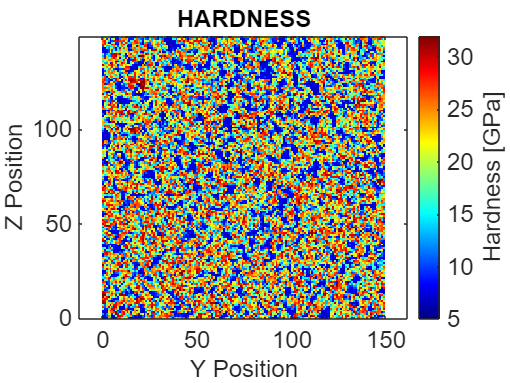

% HARDNESS pixel plot
figure

% Mostrar la matriz como una imagen de píxeles
imagesc(Y_sorted, Z_sorted, Z1_matrix_clipped);

set(gca, 'YDir', 'normal')

% Colocar la barra de color
cbar1 = colorbar;
cbar1.Label.String = 'Hardness [GPa]';
cbar1.Label.FontSize = 18;
colormap('jet')

% Modificar los límites de la colorbar
clim([vmin1, vmax1]);

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar1.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('Y Position', 'FontSize', 18);
ylabel('Z Position', 'FontSize', 18);

% Establecer el título
title('HARDNESS', 'FontSize', 18);

axis equal

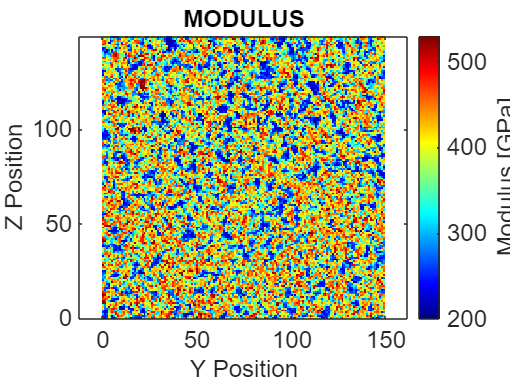


% MODULUS pixel plot
figure

% Mostrar la matriz como una imagen de píxeles
imagesc(Y_sorted, Z_sorted, Z3_matrix_clipped);

set(gca, 'YDir', 'normal')

% Colocar la barra de color
cbar2 = colorbar;
cbar2.Label.String = 'Modulus [GPa]';
cbar2.Label.FontSize = 18;
colormap('jet')

% Modificar los límites de la colorbar
clim([vmin3, vmax3]);

% Configurar el tamaño de fuente para los ejes y la barra de color
ax = gca;
ax.FontSize = 18;
cbar2.FontSize = 18;

% Configurar las etiquetas de los ejes
xlabel('Y Position', 'FontSize', 18);
ylabel('Z Position', 'FontSize', 18);

% Establecer el título
title('MODULUS', 'FontSize', 18);

axis equal